% Choose the input directory with the excel summary table for the counts
% (see example file for the shape)
dirIn = uigetdir('F:/cFOS_Validation/', 'Please choose the input directory');

% Check if the user press cancel
if isequal(dirIn,0)
    disp('User selected cancel')
    return
else
    disp(['Input directory: ', fullfile(dirIn)])
    addpath(dirIn);
end

Input directory: F:\Dropbox\Papers\cells\Figures\Figure4


Processing Manual Optimization.xlsx


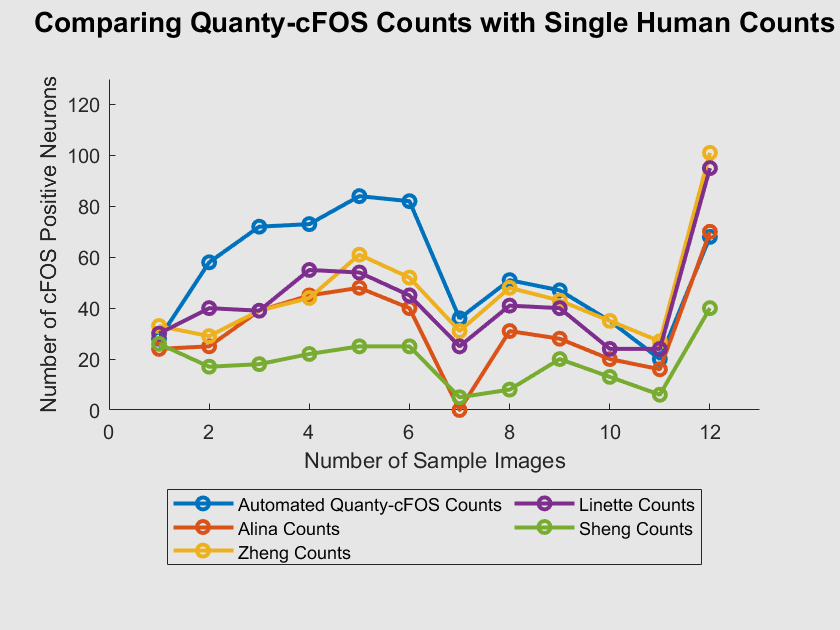

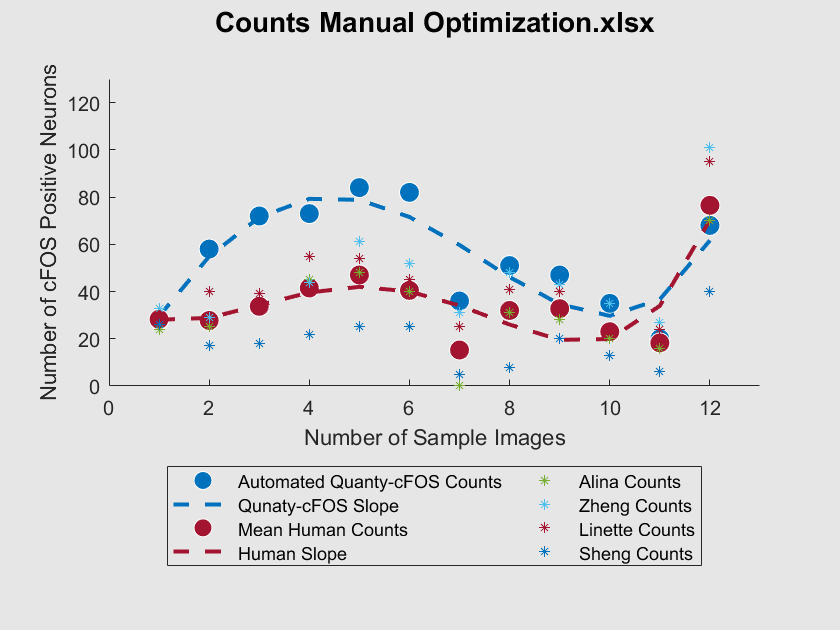

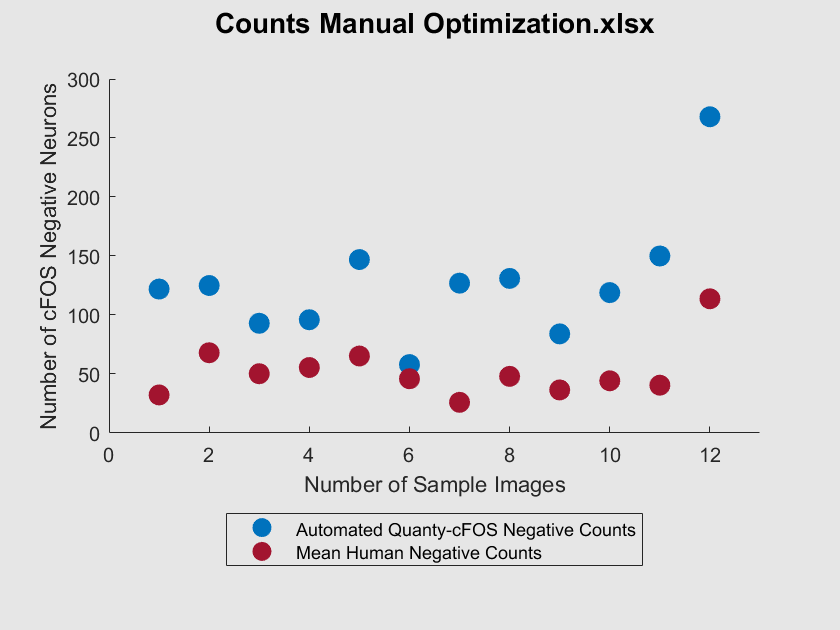

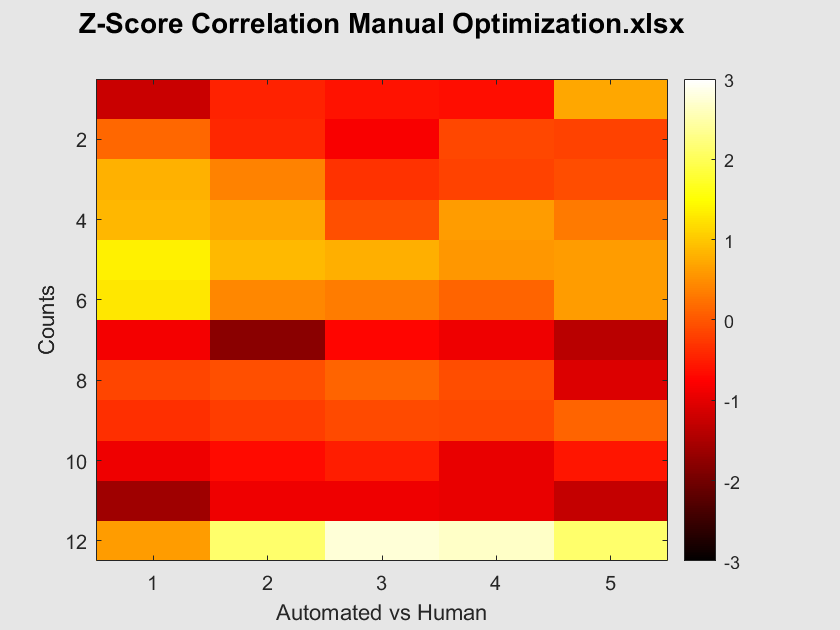

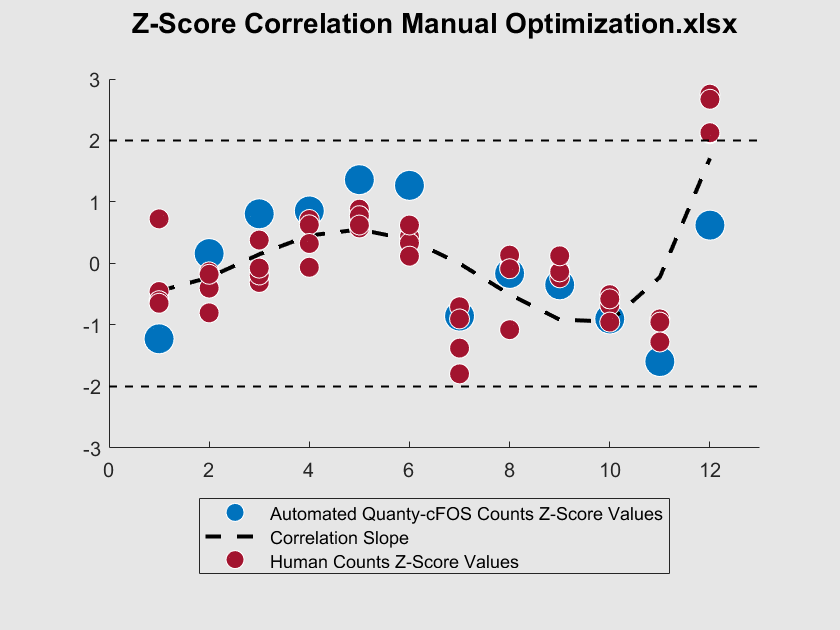


% Input data
% Get the number of .xlsx file in the input directory
fileList = dir(fullfile(dirIn,'*.xlsx'));
numberFiles = size(fileList,1);
fileID = cell(1, numberFiles);

for kk=1:numberFiles 
    
    % Get file name of the input file
    fileName = fileList(kk).name;

    % Open .xlsx file
    [~, ~, fileID{kk}] = xlsread(fileName);

    % Output the file name
    printFileName = sprintf('Processing %s', fileName);
    fprintf('%s\n', printFileName);
    
    % Shape the input (remove first 2 raws and 1 column, strings)
    % (Positive and negative values in each file are in a sequence of column)
    matrix = cell2mat(fileID{kk}(3:end,2:end));
    positive = matrix(:,1:2:end);
    negative = matrix(:,2:2:end);
    
    % Compute the mean value for human counts
    qunty_cFos_Positive = positive(:,1);
    qunty_cFos_Negative = negative(:,1);
    human_obs_Positive = mean(positive(:,2:end),2);
    merge_obs_Positive = [qunty_cFos_Positive, human_obs_Positive];
    human_obs_Negative = mean(negative(:,2:end),2);
    merge_obs_Negative = [qunty_cFos_Negative, human_obs_Negative];
    
    %% Compute the slop
    x = 1:size(matrix, 1);
    c_cFos = polyfit(x,merge_obs_Positive(:,1)',4);
    y_cFos = polyval(c_cFos,x);
    c_GT = polyfit(x,merge_obs_Positive(:,2)',4);
    y_GT = polyval(c_GT,x);
    
    % Plot values
    figure()
    hold on
    plot(merge_obs_Positive(:,1), 'o-', 'LineWidth', 2, 'color', '#0072BD')
    plot(positive(:,2:end), 'o-', 'LineWidth', 2)
    set(gca, 'color', [0.9 0.9 0.9])
    set(gcf, 'color', [0.9 0.9 0.9])
    title(sprintf('Counts %s\n', fileName), 'FontSize', 14)
    ylim([0 130])
    xlim([0 length(x)+1])
    xlabel('Number of Sample Images')
    ylabel('Number of cFOS Positive Neurons')
    lg = legend('Automated Quanty-cFOS Counts', 'Alina Counts', 'Zheng Counts', 'Linette Counts', 'Sheng Counts' ,'Location', 'southoutside');
    lg.NumColumns = 2;
    
    % Plot values
    figure()
    hold on
    plot(merge_obs_Positive(:,1), 'o', 'MarkerFaceColor', '#0072BD', 'MarkerSize', 10, 'MarkerEdgeColor','#FFFFFF')
    plot(x, y_cFos, '--', 'LineWidth', 2, 'color', '#0072BD')
    plot(merge_obs_Positive(:,2), 'o',  'MarkerFaceColor', '#A2142F', 'MarkerSize', 10, 'MarkerEdgeColor','#FFFFFF')
    plot(x, y_GT, '--', 'LineWidth', 2, 'color', '#A2142F')
    plot(positive(:,2:end), '*', 'MarkerSize', 5)
    set(gca, 'color', [0.9 0.9 0.9])
    set(gcf, 'color', [0.9 0.9 0.9])
    title(sprintf('Counts %s\n', fileName), 'FontSize', 14)
    ylim([0 130])
    xlim([0 length(x)+1])
    xlabel('Number of Sample Images')
    ylabel('Number of cFOS Positive Neurons')
    lg = legend('Automated Quanty-cFOS Counts','Qunaty-cFOS Slope', 'Mean Human Counts', 'Human Slope', 'Alina Counts', 'Zheng Counts', 'Linette Counts', 'Sheng Counts', 'Location', 'southoutside');
    lg.NumColumns = 2;
    
    % Plot negative counts
    figure()
    hold on
    plot(merge_obs_Negative(:,1), 'o', 'MarkerFaceColor', '#0072BD', 'MarkerSize',10, 'MarkerEdgeColor','#0072BD')
    plot(merge_obs_Negative(:,2), 'o',  'MarkerFaceColor', '#A2142F', 'MarkerSize',10, 'MarkerEdgeColor','#A2142F')
    set(gca, 'color', [0.9 0.9 0.9])
    set(gcf, 'color', [0.9 0.9 0.9])
    title(sprintf('Counts %s\n', fileName), 'FontSize', 14)
    xlim([0 length(x)+1])
    xlabel('Number of Sample Images')
    ylabel('Number of cFOS Negative Neurons')
    legend('Automated Quanty-cFOS Negative Counts', 'Mean Human Negative Counts', 'Location', 'southoutside');

    %% Compute the z score for correlation (heatmap)
    z = zscore(positive);
    figure()
    imagesc(z) 
    colorbar
    colormap(hot)
    caxis([-3, 3]);
    set(gcf, 'color', [0.9 0.9 0.9])
    title(sprintf('Z-Score Correlation %s\n', fileName), 'FontSize', 14)
    xlabel('Automated vs Human')
    ylabel('Counts')
    
    % Compute the slop
    y = mean(z,2)';
    c = polyfit(x,y,4);
    y_est = polyval(c,x);
    
    % Plot the value
    figure()
    hold on
    plot(z(:,1), 'o', 'MarkerFaceColor', '#0072BD', 'MarkerSize',15, 'MarkerEdgeColor','#FFFFFF')
    plot(x, y_est, '--', 'LineWidth', 2, 'color', '#000000')
    plot(z(:,2:end), 'o',  'MarkerFaceColor', '#A2142F', 'MarkerSize',10, 'MarkerEdgeColor','#FFFFFF')
    plot([0 length(x)+1], [2 2], '--', 'LineWidth', 1, 'color', '#000000')
    plot([0 length(x)+1], [-2 -2], '--', 'LineWidth', 1, 'color', '#000000')
    set(gca, 'color', [0.9 0.9 0.9])
    set(gcf, 'color', [0.9 0.9 0.9])
    title(sprintf('Z-Score Correlation %s\n', fileName), 'FontSize', 14)
    ylim([-3 3])
    xlim([0 length(x)+1])
    legend('Automated Quanty-cFOS Counts Z-Score Values', 'Correlation Slope' ,'Human Counts Z-Score Values' ,'Location', 'southoutside');
    
end